# L'automatique en MathLab

G(s) = K/(1+sT) K = 10; T = 2

-> Trouver la réponse indcielle G(s) -> " " impulsionnelle de G(s) Commentaires

G2(s) = K / [(1+sT)(1+s(T/10))] Même chose pour G2(s) Comparer les réponses 

Aide : utiliser les fonctions tf(), step, impulse methode(F) permet d'afficher tout ce qui est applicable à F

K = 10;
T = 2;

## Déclaration de la fonction de transfert :

F = tf([2 1],[1 2]);

s = tf('s');
F1 = (2*s+1)/ (s+2);
F.num;
F.den;
get(F);

       Numerator: {[2 1]}
     Denominator: {[1 2]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
              Ts: 0
        TimeUnit: 'seconds'
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
    SamplingGrid: [1×1 struct]



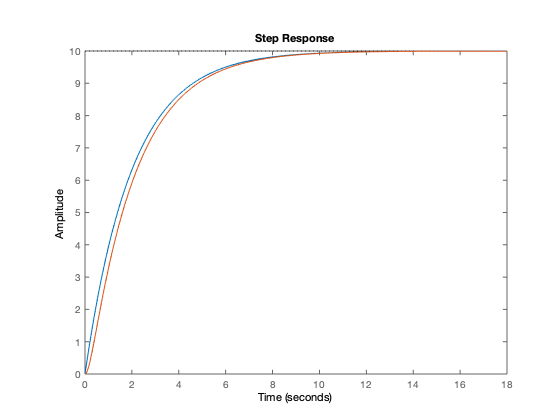

G = K / (1 + s * T);
%step(G);

G2 = K / ((1 + s * T)*(1 + s * T/10));
step(G,G2);

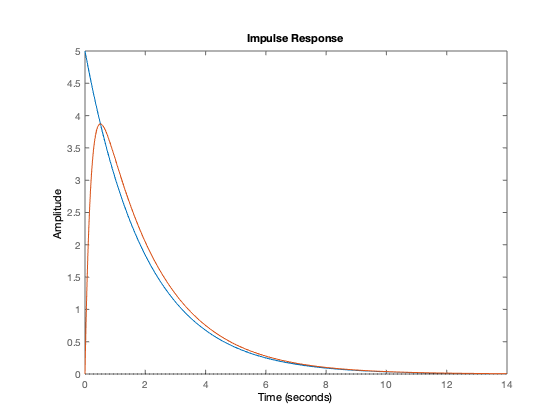

impulse(G,G2)

## La réponse impulsionnelles 

Dans le cadre d'un système de premier ordre, elle aura toujours la même tête.--> Toujours des poles réel

Dans le cas d'un second ordre, elle change en fonction des poles qui peuvent être complexe conjugué ou imaginaire.

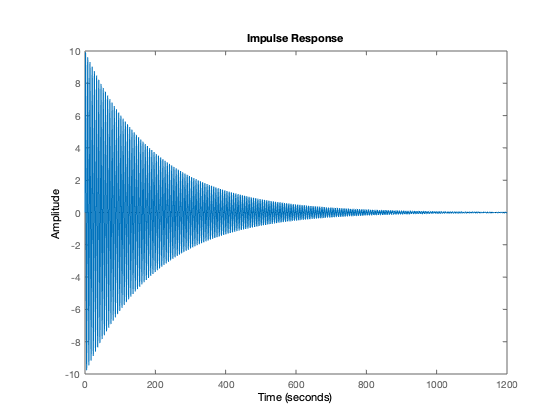

G3 = K / (s ^2 + 0.01 * s + 1 );
impulse(G3)

## Calcule des poles de la fonction : 

L'utilisation de la fonction **pole** ou encore dans les attributs (via **roots(G2.den{1}**).

pole(G2)

ans =    -5.0000
   -0.5000


roots(G2.den{1})

ans =    -5.0000
   -0.5000


roots(G3.den{1})

ans =   -0.0050 + 1.0000i
  -0.0050 - 1.0000i


##  Exercice 1 : 

Ecririe en Matlab, la réponse indicielle de : 

F(s) : e^(-2δs) / (1 + s T)

Delta = 2

T = 5

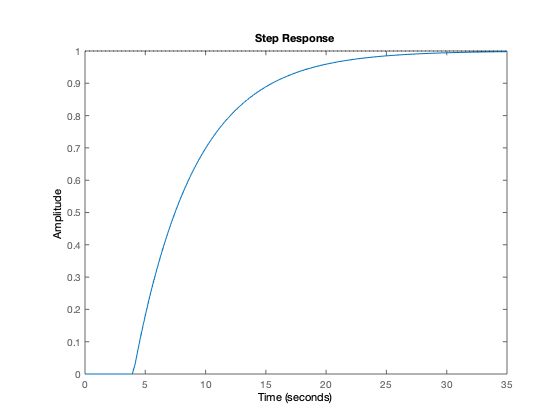

Delta = 2;
T = 5;
F = exp(-2 * Delta * s) / (1+s*T);
step(F)

On voit que la fonction est très retardée.

==> Permet de calculer le retard pure

## Fonction de Transfert sous forme factorisée

zpk(G2)


ans =
 
       25
  -------------
  (s+5) (s+0.5)
 
Continuous-time zero/pole/gain model.



## Récupérer le numérateur et le dénominateur de la fonction de transfert

[num, den] = tfdata(G2)

num = 1×1 cell array
    {1×3 double}


den = 1×1 cell array
    {1×3 double}


[num, den] = tfdata(G2, 'v')

num =      0     0   100


den =      4    22    10


## La liste des 0, des pôles et le gain du système

[z,p,k] = zpkdata(G2)

z = 1×1 cell array
    {0×1 double}


p = 1×1 cell array
    {2×1 double}


k = 25

celldisp(zpkdata(G2),'v')

 
v{1} =
 
     []
 


## Obtenir les 0 de la fonction de transfert

%roots(tf())